# Cvičení 11 - B2M31AEDA

## Nahrání dat

**Popis dat:** Pracovní data jsou uložena v souboru data.csv, který je k dispozici ke stažení na Moodle stránce tohoto předmětu, ve složce příslušného cvičení. Pro načtení dat do Matlabu využijte funkce `readtable`*.*

close all; clear; clc; addpath(genpath(fullfile([pwd '\Uni' '\grad' '\AEDA' '\week11' '\sem'])))
s = settings;
s.matlab.appearance.figure.GraphicsTheme.TemporaryValue = "light";
T = readtable('data.csv', 'ReadVariableNames', true);
untreated = [T.bradykinesia_U, T.tremor_U, T.rigidity_U, T.axial_U];
treated = [T.bradykinesia_T, T.tremor_T, T.rigidity_T, T.axial_T];

## 1. Clusterování pomocí K-means

**Použijte všechny 4 dostupné hodnocení UPDRS pro rozdělení dostupných dat do dvou skupin – clusterů. Cílem by bylo např. charakterizovat skupinu s dobou a špatnou odezvou na léky.**

- Z hodnot všech 4 UPDRS parametrů vypočítejte delty - rozdíly mezi hodnotami před a po podání léku.

- Tyto delty použijte jako vstupní data pro clusterování. Celkově tady vaše data budou 4 dimenzionální.

- Pro clusterování využijte Matlabovskou funkci `k-means`, neprogramujte proces manuálně (to je obsahem bonusové úlohy).

- K-means inicializujte náhodně a proveďte 5 iterací celého clusteringu, z nichž pak vyberte nejlepší výsledek (na základě celkového součtu vzdáleností).

- Výsledky vizualizujte pomocí funkce `visualizeKmeans` (dostupná ke stažení na Moodlu).

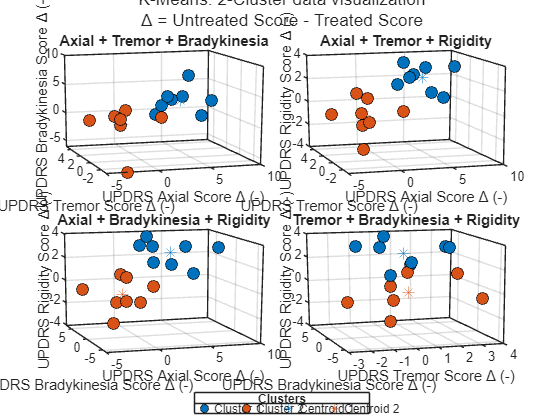

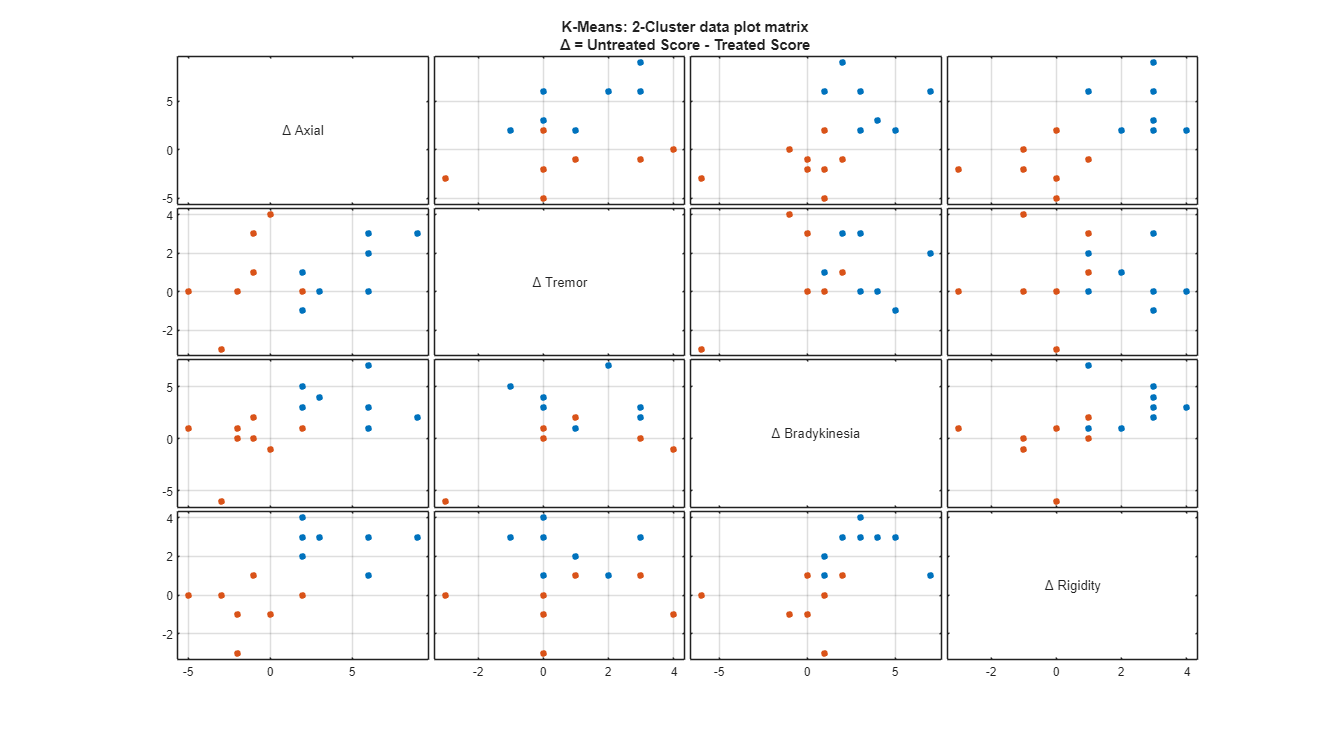

data = untreated - treated;
[kmeansIdx, kmeansCentroids] = kmeans(data, 2, 'Replicates', 5, 'Start', 'sample');

visualizeKmeans(kmeansIdx, kmeansCentroids, data);

### **Otázky:**

- **Proč je dobré celý clusterovací algoritmus několikrát opakovat?**

- **Jak byste manuálně nastavili počáteční podmínky algoritmu, tak aby algoritmus co nejrychleji zkonvergoval s co nejlepšími výsledky?**

- **Jak byste nastavili hranici pro úspěšné skončení clusterovacího algoritmu?**

### **Odpovědi:**

- Jelikož jsme volíme inicializaci clusterování náhodným výběrem z datasetu (parametr *sample*), dostáváme pro každou další replikaci různé výsledky. Opakováním algoritmu tak zvyšujeme věrohodnost výsledku.

- Mauálně lze provést inicializaci tak, že provedeme clusterování na zvoleném subsamplu a tento výsledek zvolíme jako seed pro řádné clusterování. Další možností je implementace algoritmu *k-means++*, který realizuje heuristický odhad počátečního seedu deterministickým způsobem právě za účelem zrychlení clusterování a zlepšení jeho výsledku.

- Nastavil bych zastavovací kritérium tak, aby algoritmus skončil v moment, kdy následující iterace potvrdí současnou polohu centroid.

## 2. Gaussian Mixture Model + K-means porovnání

Připravte si směs dvou normálních rozdělení – *Gaussian Mixture Model* (GMM), který bude reprezentovat vaše data.

- Vyberte si jakékoli 2 z parametrů, se kterými budete dále pracovat.

- Z těchto dvou parametrů opět vytvořte delty - rozdíly hodnot před a po podání léku. Nezapomeňte napsat jaké parametry jste si vybrali!

- Vytvořte z vybraných dat GM model s pomocí Matlabovské funkce `fitgmdist`. Proces opakujte cca 10x s náhodnou inicializací a vyberte nejlepší výsledek.

- Funkce `fitgmdist` defaultně vytváří model na základě maximálního likelihoodu, za pomocí EM (Expectation-Maximization) algoritmu.

- Inicializační kovarianční matice pro komponenty se vytvoří jako prosté diagonální matice, které na diagonále obsahují rozptyly jednotlivých datových sloupců.

- Mixing proportions (poměry míchání) jsou nastaveny rovnoměrně.

**Pro vybraná data také vypočítejte také clustery pomocí K-****means****.**

**Výsledky clusteringu pro obě metody zobrazte vedle sebe do jednoho obrázku.**

- Vhodným způsobem vyznačte příslušnost jednotlivých bodu k jedné či druhé skupině tak, jak jí přiřadil clustering.

- Vykreslete do obrázku také centroidy obou clusterů.

- Pro Gaussovský model také vykreslete do obrázku kontury jednotlivých pravděpodobnostních úrovní, případně můžete vykreslit celý obrázek ve 3D.

- Pro vizualizaci pravděpodobnostního rozdělení z GMM použijte funkci `fcontour`. Příklady použití najdete v dokumentaci k `fitgmdist` a `cluster`.

- Pokuste se nastavit kovarianční matici Gaussovského modelu tak, aby výsledek clusteringu co nejvíce odpovídal výsledku K-means.

var1 = "axial";
var2 = "bradykinesia";
data = [T.(var1 + "_U") - T.(var1 + "_T"), T.(var2 + "_U") - T.(var2 + "_T")];

gmModel = fitgmdist(data, 2, ...
    'Start', 'randSample', ...
    'Replicates', 10, ...
    'RegularizationValue', 0.01, ...
    'CovarianceType', 'full', ...
    'SharedCovariance', false, ...
    'Options', statset( ...
        'Display', 'off', ...
        'MaxIter', 1000));

**Vizualizace:**

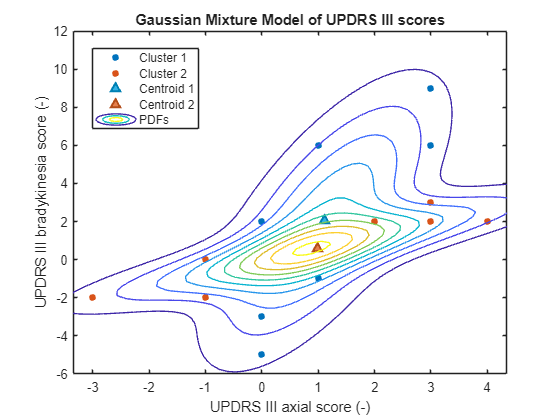

gmPDF = @(x,y) arrayfun(@(x0,y0) pdf(gmModel, [x0 y0]), x, y);
gmIdx = cluster(gmModel, data);

figure()
gscatter(data(:,1), data(:,2), gmIdx)
hold on
ax = gca;
scatter(gmModel.mu(1,1), gmModel.mu(1,2), '^', 'MarkerEdgeColor', [.0 .5 .7], 'MarkerFaceColor', [.2 .7 .9], 'LineWidth', 1.5);
scatter(gmModel.mu(2,1), gmModel.mu(2,2), '^', 'MarkerEdgeColor', [.7 .3 .1], 'MarkerFaceColor', [.9 .5 .3], 'LineWidth', 1.5);
fcontour(gmPDF, [ax.XLim(1)-1, ax.XLim(2)+1, ax.YLim(1)-1, ax.YLim(2)+1], 'LineWidth', 1);
hold off
xlabel(sprintf('UPDRS III %s score (-)', var1))
ylabel(sprintf('UPDRS III %s score (-)', var2))
legend('Cluster 1', 'Cluster 2', 'Centroid 1', 'Centroid 2', 'PDFs', 'Location', 'best')
title('Gaussian Mixture Model of UPDRS III scores')

### **Otázky:**

- **Liší se výsledné skupiny nalezené pomocí K-means a GMM?**

- **V čem je největší rozdíl mezi clusterováním pomocí K-means a pomocí GMM?**

### **Odpovědi:**

- Výsledky se pro K-means a GMM příliš neliší, neboť pracujeme s relativně malým datasamplem, který je dobře separovatelný do pravidelných clusterů. Nicméně se zdá, že GMM je metoda méně citlivá na náhodný výběr subsamplu pro inicializaci algoritmu.

- Největší rozdíl spočívá v předpokladech ohledně zpracovávaného datasetu. Zatímco algoritmus K-means dává dobré výsledky zejména pro data dobře separovatelných do sférických clusterů podobných velikostí, algoritmus GMM je komplexnější, a tudíž výpočetně náročnější, ale dosahuje přesnějších výsledků i pro data, která se clusterují do různých tvarů o různých velikostech. Výrazným rozdílem je také fakt, že zatímco výpočet K-means je založen na středních hodnotách, a je tak citlivější na přítomnost outlierů, GMM modeluje data jako kombinaci Gaussovských distribucí, a tak vykazuje vyšší robustnost i v tomto ohledu.

## 3. Klasifikační experiment

**Zkombinujte vědomosti z tohoto a předešlého cvičení a proveďte klasifikační experiment. Zkuste predikovat, jak bude pacient odpovídat na léčbu jen základě hodnot všech UPDRS parametrů vyhodnocených před podáním léku.**

- Použijte clustering pro **rozřazení dat pro trénování SVM modelu do dvou skupin:** a) Skupiny, která reaguje na léčbu dobře, b) do skupiny, která na léčbu reaguje špatně (nebo vůbec).

- Reakci na léčbu berte opět **na základě delta ****Δ**** hodnot** všech UPDRS hodnocení (rozdíly mezi hodnotami před a po podání léku).

- Pro clusterování opět využijte k-means: 2 skupiny, náhodná inicializace, min. 5 replikací.

- S pomocí olabelovaných dat **natrénujte SVM model s RBF kernelem** – pro trénování použijte hodnocení UPDRS **před** **podáním léku** (aby model mohl klasifikovat pacienty pomocí klinického vyšetření předtím, než dostanou lék, a my bychom tak mohli vědět, zdali na něj budou reagovat dobře, či ne).

- Optimální parametry SVM modelu (*C*  a *σ*) zjistěte pomocí techniky *Grid Search* na cross-validovaných datech metodou *leave-one-out*, stejně jako na minulém cvičení.

- Hyperparametry RBF kernelu *BoxConstraint* a *KernelScale*  procházejte opět na mřížce mezi hodnotami 0.1 až 3.01 s krokem 0.1.

- Pro vizualizaci a nalezení optimálních hodnot hyperparametrů z mřížky můžete opět použít přiloženou funkci `plotGridSearch`.

**Pro optimálně nastavený SVM s RBF kernelem vypočítejte hodnoty senzitivity, specificity a accuracy pro cross-validovaný model metodou *****leave-out-out*****. Výsledky také můžete vykreslit pomocí **`confusionchart`**.**

**Stručně slovně zhodnoťte výsledek klasifikačního experimentu a zdali by bylo možné použít jeho výsledky v praxi. **

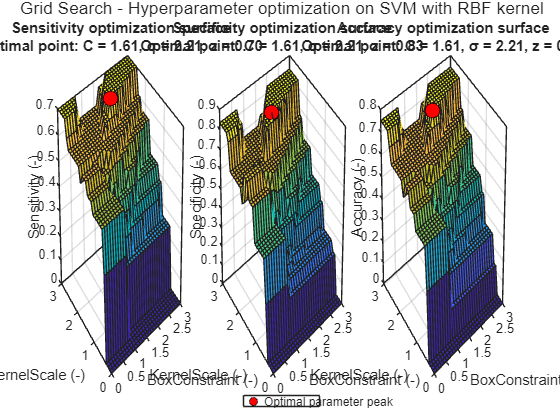

data = untreated - treated;
[kmeansIdx, ~] = kmeans(data, 2, 'Replicates', 10, 'Start', 'sample');

[BoxConstraint, KernelScale] = deal(0.01:0.1:3.01);
parameters = nan(length(BoxConstraint), length(BoxConstraint), 3);
for i = 1:length(BoxConstraint)
    for j = 1:length(BoxConstraint)
        CVmodel_RBF = fitcsvm(untreated, kmeansIdx, ...
            'Standardize', true, ...
            'KernelFunction', 'RBF', ...
            'BoxConstraint', BoxConstraint(i), ...
            'KernelScale', KernelScale(j), ...
            'CrossVal', 'on', ...
            'Leaveout', 'on');
        label_CV = kfoldPredict(CVmodel_RBF);
        confusionMatrix = confusionmat(kmeansIdx, label_CV);
        parameters(i,j,1) = confusionMatrix(2,2)/(confusionMatrix(2,2)+confusionMatrix(1,2));
        parameters(i,j,2) = confusionMatrix(1,1)/(confusionMatrix(1,1)+confusionMatrix(2,1));
        parameters(i,j,3) = sum(diag(confusionMatrix))/sum(sum(confusionMatrix));
    end
end

figure
GridSearch = plotGridSearch(BoxConstraint, KernelScale, parameters);

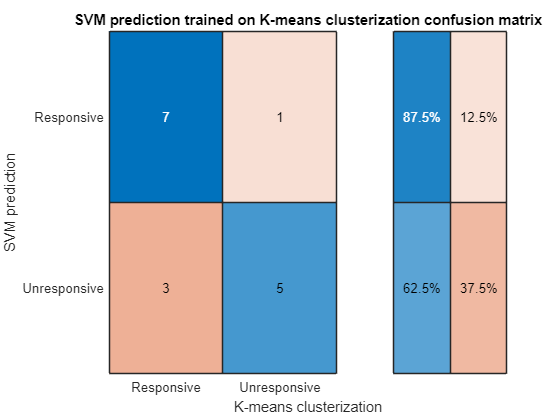

CVmodel_RBF = fitcsvm(untreated, kmeansIdx, ...
    'Standardize', true, ...
    'KernelFunction', 'RBF', ...
    'BoxConstraint', GridSearch{3,1}, ...
    'KernelScale', GridSearch{3,2}, ...
    'CrossVal', 'on', ...
    'Leaveout', 'on');
label_CV = kfoldPredict(CVmodel_RBF);
confusionMatrix = confusionmat(kmeansIdx == 2, label_CV == 2);

figure
confusionchart(confusionMatrix, {'Unresponsive', 'Responsive'}, ...
    'XLabel', 'K-means clusterization', ...
    'YLabel', 'SVM prediction', ...
    'RowSummary', 'row-normalized');
title('SVM prediction trained on K-means clusterization confusion matrix');

### **Odpovědi:**

fprintf("Optimal parameters C = %.3f and sigma = %.3f found using the grid-search technique yield the Sensitivity value of %.3f.", ...
    GridSearch{1,1}, GridSearch{1,2}, GridSearch{1,3});

Optimal parameters C = 1.610 and sigma = 2.210 found using the grid-search technique yield the Sensitivity value of 0.700.

fprintf("Optimal parameters C = %.3f and sigma = %.3f found using the grid-search technique yield the Specificity value of %.3f.", ...
    GridSearch{2,1}, GridSearch{2,2}, GridSearch{2,3});

Optimal parameters C = 1.610 and sigma = 2.210 found using the grid-search technique yield the Specificity value of 0.833.

fprintf("Optimal parameters C = %.3f and sigma = %.3f found using the grid-search technique yield the Accuracy value of %.3f.", ...
    GridSearch{3,1}, GridSearch{3,2}, GridSearch{3,3});

Optimal parameters C = 1.610 and sigma = 2.210 found using the grid-search technique yield the Accuracy value of 0.750.

Jak je vidět jak na výsledcích techniky *grid search*, tak na úspěšnosti predikce v podobě *confusion matrix*, můžeme považovat klasifikační experiment za povedený.

fprintf('I can''t get rid of this error:\n\n')

I can't get rid of this error:

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;

Error in 

## Nepovinný bonus:

**BUĎ: (za 0.5 bodu)**

Implementujte manuálně algoritmus K-means, který bude fungovat ve více dimenzích. Algoritmus otestujte na datasetu bonus.csv (k dispozici ke stažení na Moodlu).

**NEBO: (za 1 bod)**

Implementujte manuálně algoritmus EM pro vícedimenzionální data, obsahující směs dvou normálních rozdělení – bonus.csv. Pokud chcete, můžete z dat použít pouze libovolné dvě dimenze a výsledek si pak vykreslit pomocí grafů `scatter` a `contour`.

% Váš kód:

